clear

% Define Beam properties
base = sym(0.005);
height = sym(0.005);
I = base*height^3 / 12;
E = sym(1000000);

% Specify load and boundary conditions
syms f(x)
f(x) = (erf((x-1/2)*4)-0.9) * height^3;% piecewise(0<=x & x<0.5,10*height^3, 0.5<x & x<=1,-1*height^3); %(10*cos(3/2*pi*x)+10*sin(5/3*pi*x)) * height^3 ; %10*height^3;
g = sym(0);
h = sym(0);
m = sym(0);% sym(-4*height^3);
q = sym(0);%sym(-4*height^3);

% Compute the Exact Solution
EX = computeExactSolution(E,I,f,g,h,m,q);
% deg_exact_solution = polynomialDegree(EX.U)

% Prepare the FEA solution
nELEM = 2;
eDegree = 4 %deg_exact_solution - 4

eDegree = 4

continuity = eDegree - 1

continuity = 3

contVector = [-1 continuity*ones(1,nELEM-1) -1];

% Compute the FEA solution
FE = main(nELEM, eDegree, contVector, f, g, h, m, q, E*I);

% Get the exact solution at x = 1
EX.U(1)

$$ans = \frac{947\,\mathrm{erf}\left(2\right)}{5120000}+\frac{133\,{\mathrm{e}}^{-4}}{1280000\,\sqrt{\pi }}-\frac{27}{100000}$$

% Get the FEA solution at x = 1
FE.U(1)

$$ans = -\frac{389989866414211}{4611686018427387904}$$


% figure
% hold on
% fplot(f,EX.domain)
% plot(FE.Spline.nodes(3:end), FE.LinearSystem.F,'-o')

## About the Datastructures

% Exact Solution datastructure
EX

EX = struct with fields:
         f: [1×1 symfun]
       eqn: [1×1 symfun]
      cond: [1×4 sym]
    domain: [0 1]
         U: [1×1 symfun]


EX.f % The forcing function f(x)

$$ans(x) = \frac{\mathrm{erf}\left(4\,x-2\right)}{8000000}-\frac{9}{80000000}$$

EX.eqn % The equation we're solving

$$ans(x) = \frac{\partial^{4}}{\partial x^{4}}u\left(x\right)=\frac{3\,\mathrm{erf}\left(4\,x-2\right)}{1250}-\frac{27}{12500}$$

EX.cond % The boundary conditions

$$ans = \left(\begin{array}{cccc} u\left(0\right)=0 & \left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)\right)|}_{x=1}\right)=0 & \left({\left(\frac{\partial^{3}}{\partial x^{3}}u\left(x\right)\right)|}_{x=1}\right)=0 \end{array}\right)$$

EX.domain % The domain we're solving over

ans =      0     1


EX.U % The solution u(x)

$$ans(x) = \frac{23\,\mathrm{erf}\left(2\right)}{2048000}+\frac{23\,\mathrm{erf}\left(4\,x-2\right)}{2048000}-x\,\left(\frac{11\,\mathrm{erf}\left(2\right)}{160000}+\frac{{\mathrm{e}}^{-4}}{32000\,\sqrt{\pi }}\right)-\frac{11\,x\,\mathrm{erf}\left(4\,x-2\right)}{160000}+\frac{13\,{\mathrm{e}}^{-4}}{2560000\,\sqrt{\pi }}-\frac{x^{3}\,\left(\frac{3\,\mathrm{erf}\left(2\right)}{2500}+\frac{3\,{\mathrm{e}}^{-4}}{5000\,\sqrt{\pi }}-\frac{27}{12500}\right)}{6}+\frac{x^{2}\,\left(\frac{69\,\mathrm{erf}\left(2\right)}{80000}+\frac{9\,{\mathrm{e}}^{-4}}{20000\,\sqrt{\pi }}-\frac{27}{25000}\right)}{2}+\frac{27\,x^{2}\,\mathrm{erf}\left(4\,x-2\right)}{160000}-\frac{x^{3}\,\mathrm{erf}\left(4\,x-2\right)}{5000}+\frac{x^{4}\,\mathrm{erf}\left(4\,x-2\right)}{10000}-\frac{9\,x^{4}}{100000}-\frac{13\,{\mathrm{e}}^{-16\,x^{2}+16\,x-4}}{2560000\,\sqrt{\pi }}+\frac{29\,x\,{\mathrm{e}}^{-16\,x^{2}+16\,x-4}}{1280000\,\sqrt{\pi }}-\frac{3\,x^{2}\,{\mathrm{e}}^{-16\,x^{2}+16\,x-4}}{80000\,\sqrt{\pi }}+\frac{x^{3}\,{\mathrm{e}}^{-16\,x^{2}+16\,x-4}}{40000\,\sqrt{\pi }}$$


% Finite Element Solution datastructure
FE

FE = struct with fields:
        Elements: [1×2 struct]
          Spline: [1×1 bspline]
               U: [1×1 symfun]
    LinearSystem: [1×1 struct]


FE.Elements % Structure of all the finite elements

ans = 1×2 struct array with fields:
    GDomain
    GNodes
    GDOF
    GbFun
    GBasisFuns
    GInterpFun
    G_EI
    LDomain
    LNodes
    LDOF
    LbFun
    LBasisFuns
    LDerivBasisFuns
    LInterpFun
    GlobalVariate_to_LocalVariate
    LocalVariate_to_GlobalVariate
    Jacobian_Global_to_LocalVariate
    Jacobian_Local_to_GlobalVariate
    Hessian_Global_to_LocalVariate
    Hessian_Local_to_GlobalVariate


FE.Spline % The B-Spline from which we computed things like extraction operators

ans =   bspline with properties:

                 degree: 4
       continuityVector: [-1 3 -1]
               numcells: 2
             knotVector: [0 0 0 0 0 0.5000 1 1 1 1 1]
      uniqueKnotsVector: [0 0.5000 1]
         referenceNodes: []
                  nodes: [6×1 sym]
    elementConnectivity: [5×2 double]
                  basis: [1×1 struct]
          decomposition: [1×1 struct]


FE.LinearSystem % Structure of the linear system of equations, K d = F

ans = struct with fields:
    K: [4×4 sym]
    F: [4×1 sym]
    d: [6×1 sym]


FE.U % The solution u(x)

## Plots

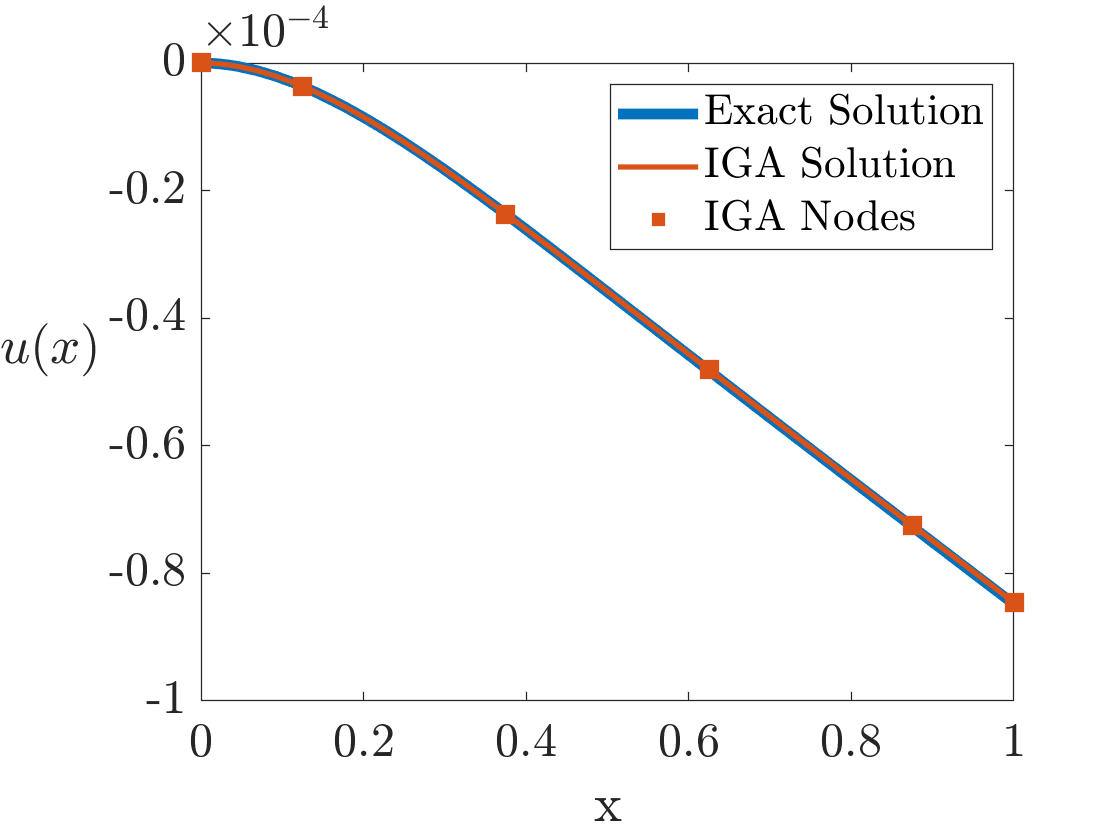

%%% Plot the exact and FEA solutions %%%
figure
hold on
fplot(EX.U,EX.domain,"LineWidth",4)
fplot(FE.U,EX.domain,"LineWidth",2)

cmap = colormap("lines");
x = [];
y = [];
for ii = 1:length(FE.Spline.nodes)
    if ii == 1
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(FE.U,sym('x'),FE.Spline.nodes(ii),'right');
    elseif ii == length(FE.Spline.nodes)
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(FE.U,sym('x'),FE.Spline.nodes(ii),'left');
    else
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(FE.U,sym('x'),FE.Spline.nodes(ii),'right');
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(FE.U,sym('x'),FE.Spline.nodes(ii),'left');
    end
end
scatter(x,y,78,"Marker",'s',"MarkerFaceColor",cmap(2,:),"MarkerEdgeColor",cmap(2,:))
legend(["Exact Solution","IGA Solution","IGA Nodes"],"Interpreter","latex","Location","northeast")
xlabel("x","Interpreter","latex")
ylabel("$u(x)$","Interpreter","latex","Rotation",0,"HorizontalAlignment","right")
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = "latex";
ax.Box = "on";

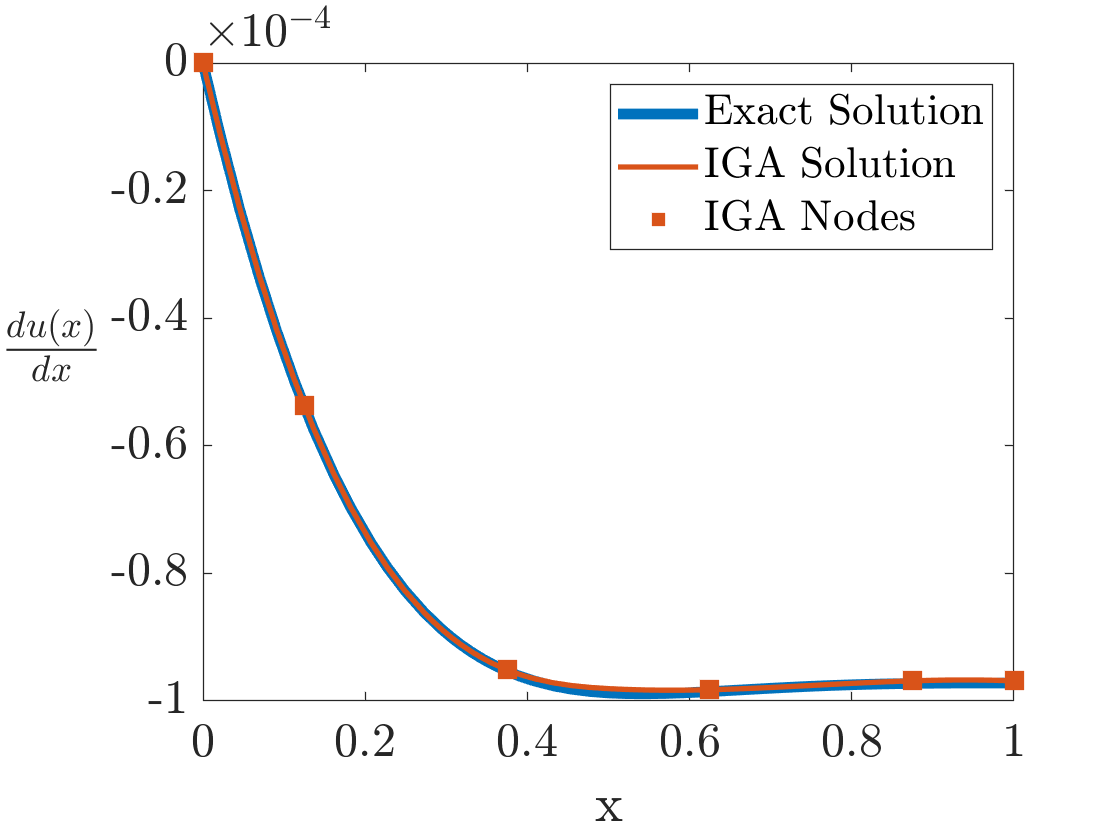


%%% Plot the derivatives of the exact and FEA solutions %%%
figure
hold on
fplot(diff(EX.U),EX.domain,"LineWidth",4)
fplot(diff(FE.U),EX.domain,"LineWidth",2)

cmap = colormap("lines");
x = [];
y = [];
for ii = 1:length(FE.Spline.nodes)
    if ii == 1
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,1),sym('x'),FE.Spline.nodes(ii),'right');
    elseif ii == length(FE.Spline.nodes)
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,1),sym('x'),FE.Spline.nodes(ii),'left');
    else
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,1),sym('x'),FE.Spline.nodes(ii),'right');
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,1),sym('x'),FE.Spline.nodes(ii),'left');
    end
end
scatter(x,y,78,"Marker",'s',"MarkerFaceColor",cmap(2,:),"MarkerEdgeColor",cmap(2,:))
legend(["Exact Solution","IGA Solution","IGA Nodes"],"Interpreter","latex","Location","northeast")
xlabel("x","Interpreter","latex")
ylabel("$\frac{du(x)}{dx}$","Interpreter","latex","Rotation",0,"HorizontalAlignment","right")
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = "latex";
ax.Box = "on";

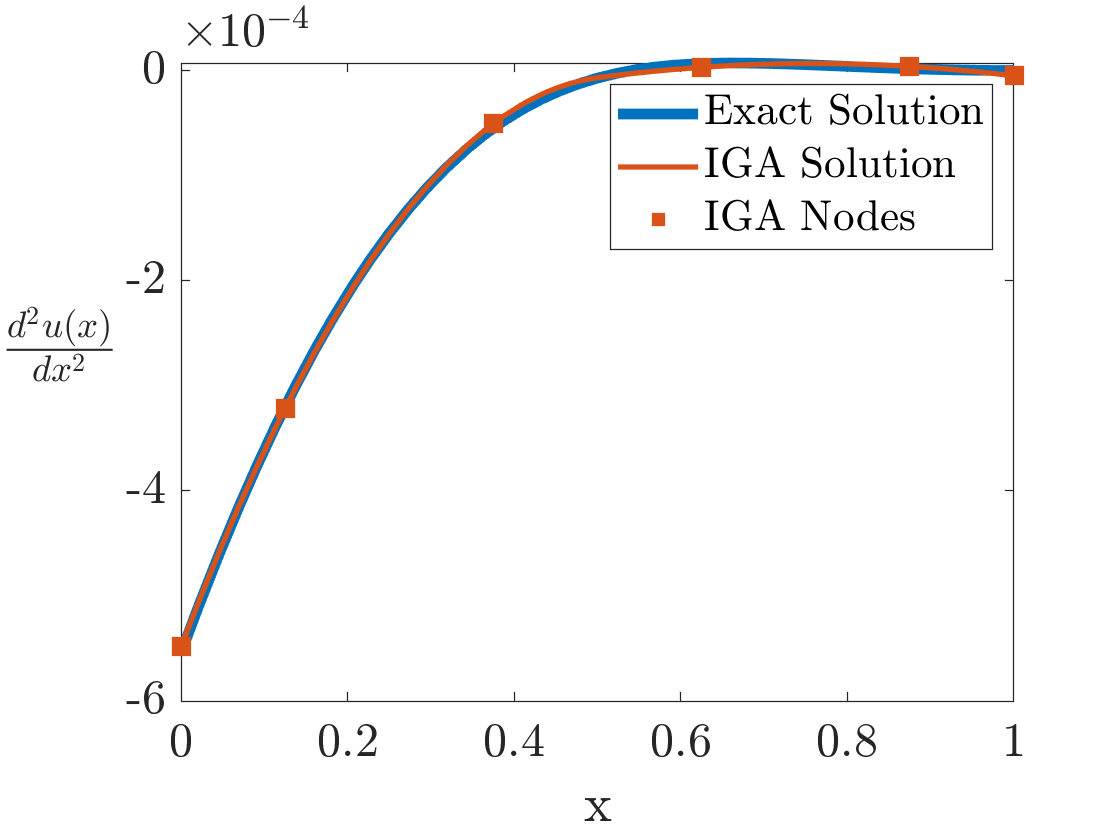



%%% Plot the second derivatives of the exact and FEA solutions %%%
figure
hold on
fplot(diff(EX.U,2),EX.domain,"LineWidth",4)
fplot(diff(FE.U,2),EX.domain,"LineWidth",2)

cmap = colormap("lines");
x = [];
y = [];
for ii = 1:length(FE.Spline.nodes)
    if ii == 1
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,2),sym('x'),FE.Spline.nodes(ii),'right');
    elseif ii == length(FE.Spline.nodes)
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,2),sym('x'),FE.Spline.nodes(ii),'left');
    else
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,2),sym('x'),FE.Spline.nodes(ii),'right');
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,2),sym('x'),FE.Spline.nodes(ii),'left');
    end
end
scatter(x,y,78,"Marker",'s',"MarkerFaceColor",cmap(2,:),"MarkerEdgeColor",cmap(2,:))
legend(["Exact Solution","IGA Solution","IGA Nodes"],"Interpreter","latex","Location","northeast")
xlabel("x","Interpreter","latex")
ylabel("$\frac{d^2u(x)}{dx^2}$","Interpreter","latex","Rotation",0,"HorizontalAlignment","right")
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = "latex";
ax.Box = "on";

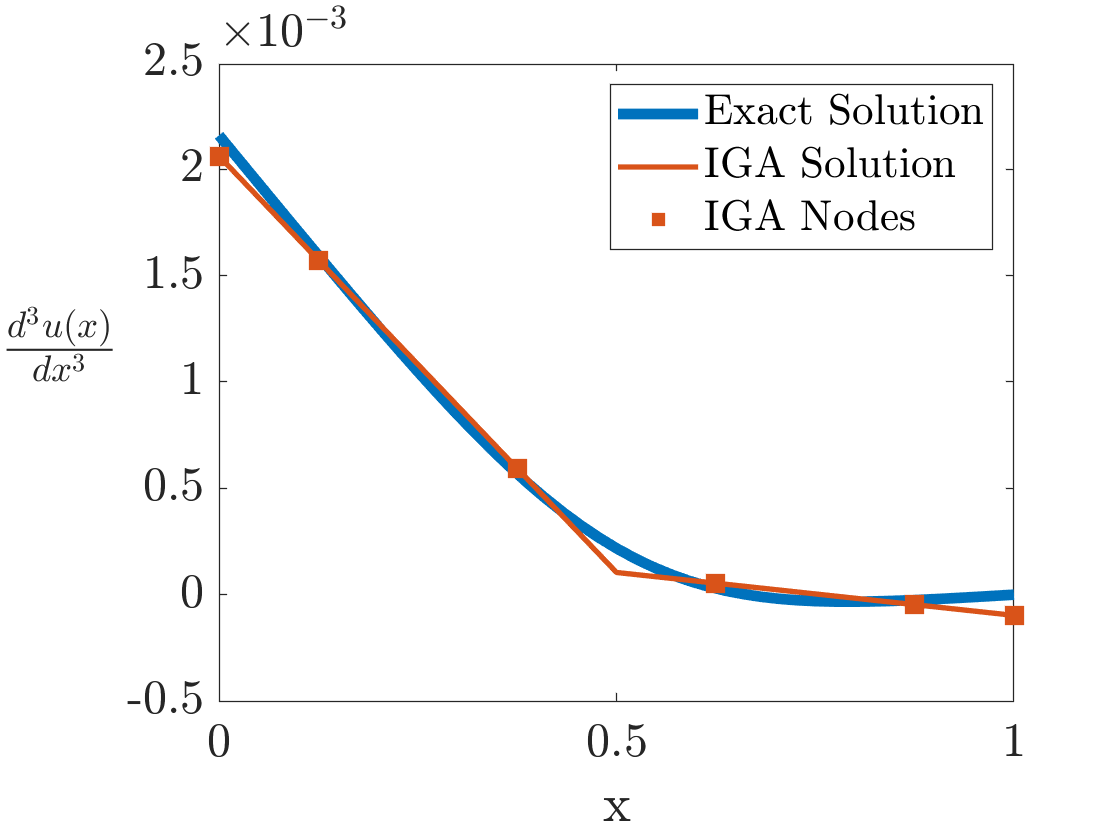


%%% Plot the third derivatives of the exact and FEA solutions %%%
figure
hold on
fplot(diff(EX.U,3),EX.domain,"LineWidth",4)
fplot(diff(FE.U,3),EX.domain,"LineWidth",2)

cmap = colormap("lines");
x = [];
y = [];
for ii = 1:length(FE.Spline.nodes)
    if ii == 1
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,3),sym('x'),FE.Spline.nodes(ii),'right');
    elseif ii == length(FE.Spline.nodes)
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,3),sym('x'),FE.Spline.nodes(ii),'left');
    else
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,3),sym('x'),FE.Spline.nodes(ii),'right');
        x(end+1) = FE.Spline.nodes(ii);
        y(end+1) = limit(diff(FE.U,3),sym('x'),FE.Spline.nodes(ii),'left');
    end
end
scatter(x,y,78,"Marker",'s',"MarkerFaceColor",cmap(2,:),"MarkerEdgeColor",cmap(2,:))
legend(["Exact Solution","IGA Solution","IGA Nodes"],"Interpreter","latex","Location","northeast")
xlabel("x","Interpreter","latex")
ylabel("$\frac{d^3u(x)}{dx^3}$","Interpreter","latex","Rotation",0,"HorizontalAlignment","right")
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = "latex";
ax.Box = "on";

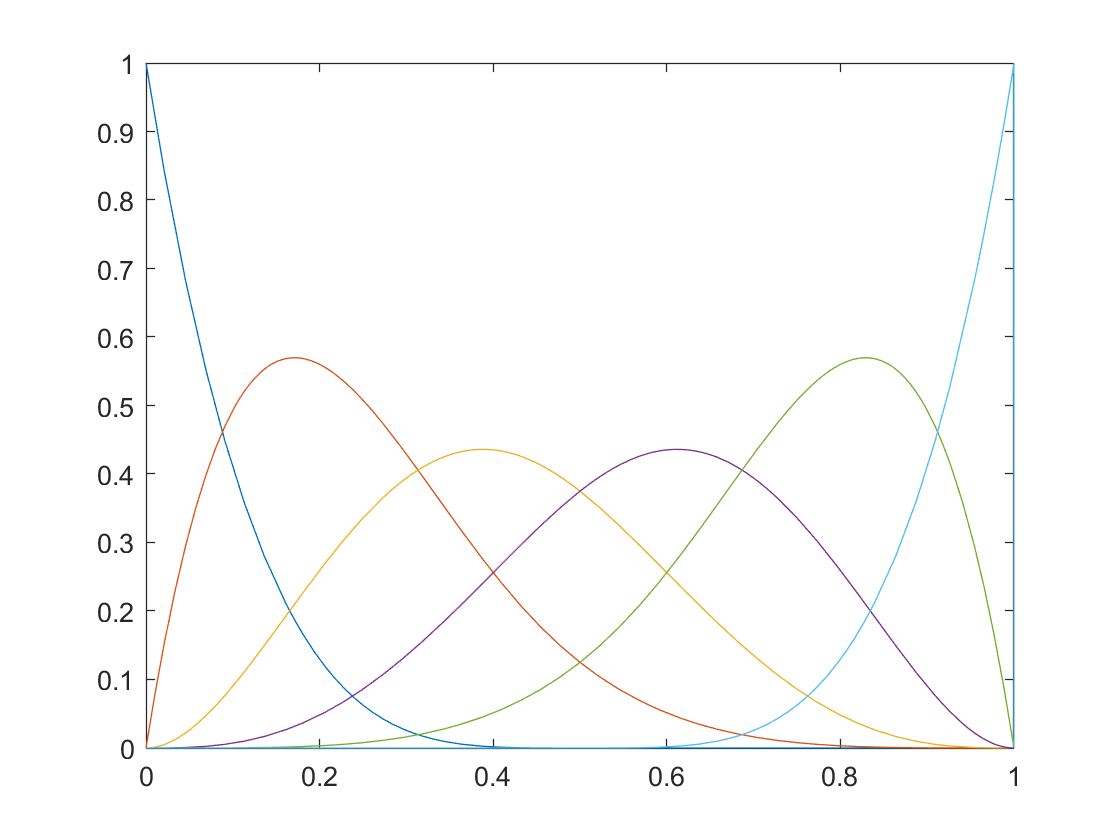


%%% Plot the Spline basis functions %%%
figure
fplot(FE.Spline.basis.functions,EX.domain)

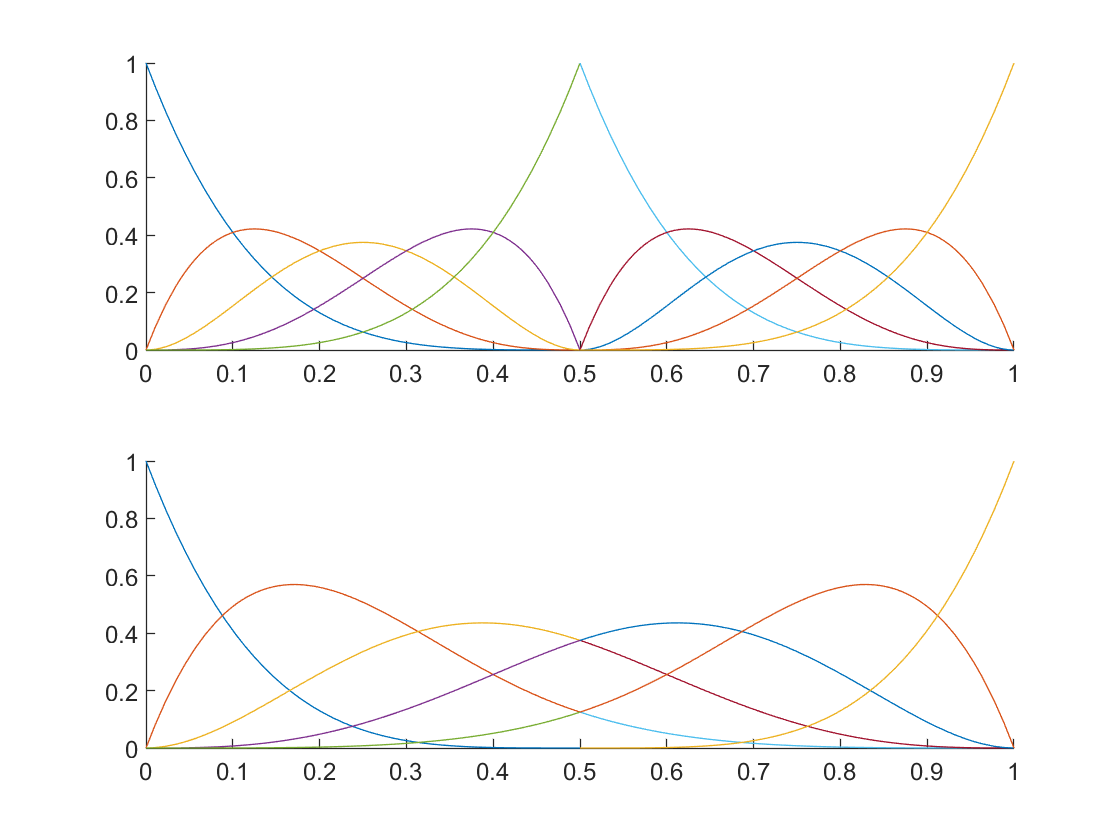


%%% Loop through each element and plot their global basis functions %%%
figure
% First plot the global Bernstein functions
subplot(2,1,1)
hold on
for e = 1:length(FE.Elements)
    fplot(FE.Elements(e).GBasisFuns,FE.Elements(e).GDomain)
end

% Secondly plot the global smooth basis functions
C = FE.Spline.decomposition.localExtractionOperator; % Get element local extraction operators
subplot(2,1,2)
hold on
for e = 1:length(FE.Elements)
    fplot(C{e}*FE.Elements(e).GBasisFuns,FE.Elements(e).GDomain)
end

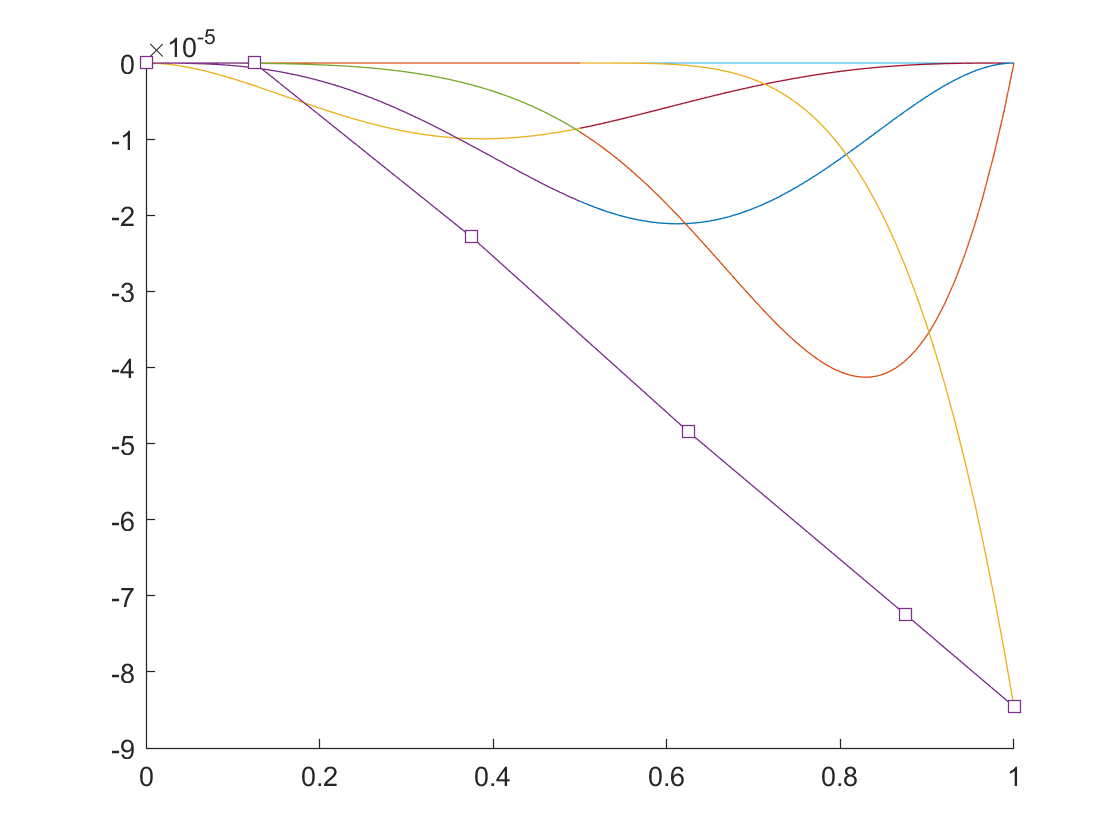


%%% Plot the basis functions scaled by the solution vector %%%
figure
hold on
bFunMap = FE.Spline.decomposition.localExtractionSupportedSplineBases;
for e = 1:length(FE.Elements)
    fplot(C{e}*FE.Elements(e).GBasisFuns .* FE.LinearSystem.d(bFunMap{e}),FE.Elements(e).GDomain)
end
% Add plot of the solution vector
plot(FE.Spline.nodes, FE.LinearSystem.d,'Marker','s','MarkerFaceColor','auto')